# Question 2: Condition Number and Sensitivity

This problem explores the concept of **matrix conditioning**. We will investigate a "nearly singular" matrix B. Such matrices are called **ill-conditioned**, and they are problematic because small changes in the input of a system Bx=b can lead to dramatically large changes in the output solution x.

**(a) Generate a Random Vector b**

To set up the linear system Bx=b, we need a vector b. We will generate a random 3times1 column vector where each element is drawn from a **uniform distribution** between 0 and 1. This ensures we are testing the system with a generic, non-special right-hand side vector.

**MATLAB Code**

%% Part (a): Define Matrix B and Generate Vector b

% Clear workspace from previous question
clear; clc; close all;

% Define the nearly singular 3x3 matrix B
B = [1   2      3;
     2   4.0001 6;
     3   6      9];

% Generate a random 3x1 vector b with elements from U[0,1]
b = rand(3, 1);

% Display the generated vector
disp('Matrix B:');

Matrix B:


disp(B);

    1.0000    2.0000    3.0000
    2.0000    4.0001    6.0000
    3.0000    6.0000    9.0000



disp('Generated vector b:');

Generated vector b:


disp(b);

    0.8656
    0.3317
    0.6954



**(b) Compute the Condition Number**

**Report**

**Concept and Method**The **condition number**, denoted kappa(B), is a crucial metric that quantifies the sensitivity of the solution x to perturbations in b. The formal definition for the 2-norm is: 

$\kappa_2$$\left(B\right)=||B||_2 ||B^{-1} ||_2 =\frac{\sigma_{\max } }{\sigma_{\min } }$��

where sigma max and sigma min are the largest and smallest singular values of B.

- A **low** condition number (close to 1) means the matrix is **well-conditioned**. Small relative errors in b lead to similarly small relative errors in x.

- A **high** condition number means the matrix is **ill-conditioned**. Small relative errors in b can be amplified into enormous relative errors in x.

The matrix B is nearly singular because its second and third rows are almost linear multiples of the first row. A perfectly singular matrix would have a condition number of infinity. Therefore, we expect kappa(B) to be a very large number.

**MATLAB Code**

%% Part (b): Compute the Condition Number

% Compute the condition number of B using the 2-norm (default for cond)
kappa_B = cond(B);

fprintf('The condition number of B is: %.4e\n', kappa_B);

The condition number of B is: 1.4189e+16


% The 'e' format is for scientific notation, which is useful for very large numbers.

**(c) Solve the System and Compute Relative Error**

**Concept and Method**The condition number provides an upper bound on the error amplification. The key relationship is: 

$\frac{||\Delta x||}{||x||}\le \kappa \left(B\right)\frac{||\Delta b||}{||b||}$�

This inequality states that the relative error in the solution ($\frac{||\Delta x||}{||x||}$) is at most the condition number times the relative perturbation in the input ($\frac{||\Delta b||}{||b||}$).

To demonstrate this, we will perform the following steps:

- Solve the original system Bx=b for x.

- Create a very small, single perturbation Deltab and add it to b to get a new vector b_pert.

- Solve the new system Bx_pert=b_pert for x_pert.

- Calculate the relative change in b and the resulting relative error in x.

- Compare the ratio of these errors to the condition number.

**MATLAB Code**

%% Part (c): Solve System and Demonstrate Error Amplification

% 1. Solve the original system Bx = b
x = B \ b;


% 2. Create a small perturbation for b. Let's use a magnitude of 1e-8.
delta_b = 1e-8 * randn(3, 1);
b_pert = b + delta_b;

% 3. Solve the perturbed system
x_pert = B \ b_pert;


% 4. Compute the relative errors
rel_error_b = norm(delta_b) / norm(b);
rel_error_x = norm(x_pert - x) / norm(x);

% 5. Calculate the amplification factor and display results
amplification_factor = rel_error_x / rel_error_b;

disp('--- Single Perturbation Analysis ---');

--- Single Perturbation Analysis ---


fprintf('Relative perturbation in b: %.4e\n', rel_error_b);

Relative perturbation in b: 1.2589e-08


fprintf('Resulting relative error in x: %.4e\n', rel_error_x);

Resulting relative error in x: NaN


fprintf('Error amplification factor: %.4e\n', amplification_factor);

Error amplification factor: NaN


fprintf('This factor is less than or equal to the condition number (%.4e).\n', kappa_B);

This factor is less than or equal to the condition number (1.4189e+16).


**(d) Systematic Perturbation and Conclusion**

**Concept and Method**

To visualize the effect of the high condition number more systematically, we will now perturb the vector b with Gaussian noise, etasimmathcalN(0,epsilon2I), for a range of different noise levels, epsilon. We will vary epsilon over several orders of magnitude (from very small to moderately small).

For each epsilon, we will calculate the resulting relative error in the solution x. We will then plot the solution error as a function of epsilon. A `loglog` plot is ideal for this, as it clearly shows the proportional relationship across a wide range of values.

**Conclusion**

The plot will show a clear, roughly linear relationship between the size of the input perturbation (epsilon) and the magnitude of the solution error. This graphically demonstrates that for an ill-conditioned matrix like B, any small error or uncertainty in the input vector b is massively amplified in the calculated solution x. The conclusion is that solutions to systems involving this matrix are highly unreliable and sensitive to input noise. This is the practical consequence of a large condition number.

**MATLAB Code**

%% Part (d): Systematic Perturbation Analysis and Plot

% 1. Create a vector of epsilon values (noise levels)
% logspace(-16, -2, 100) creates 100 points from 10^-16 to 10^-2
epsilon_values = logspace(-16, -2, 100);

% Initialize an array to store the solution errors
solution_errors = zeros(size(epsilon_values));

% 2. Loop through each epsilon value
for i = 1:length(epsilon_values)
    epsilon = epsilon_values(i);
    
    % Generate Gaussian noise with standard deviation epsilon
    delta_b_loop = epsilon * randn(3, 1);
    
    % Create the perturbed b
    b_pert_loop = b + delta_b_loop;
    
    % Solve the perturbed system
    x_pert_loop = B \ b_pert_loop;
    
    % Calculate and store the relative error in the solution
    solution_errors(i) = norm(x_pert_loop - x) / norm(x);
end

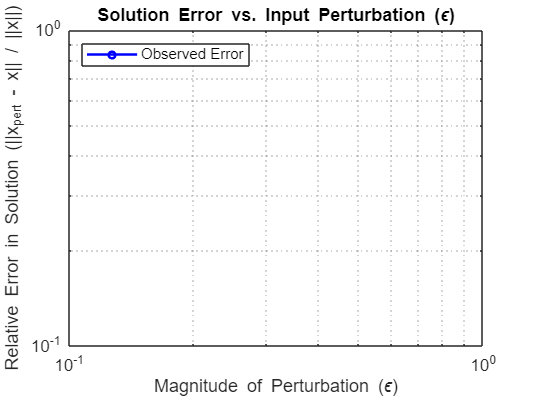


% 3. Plot the results on a log-log scale
figure;
loglog(epsilon_values, solution_errors, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4);
grid on;
title('Solution Error vs. Input Perturbation (\epsilon)');
xlabel('Magnitude of Perturbation (\epsilon)');
ylabel('Relative Error in Solution (||x_{pert} - x|| / ||x||)');
legend('Observed Error', 'Location', 'northwest');